close all

**Plane stress transformation: cutting plane**

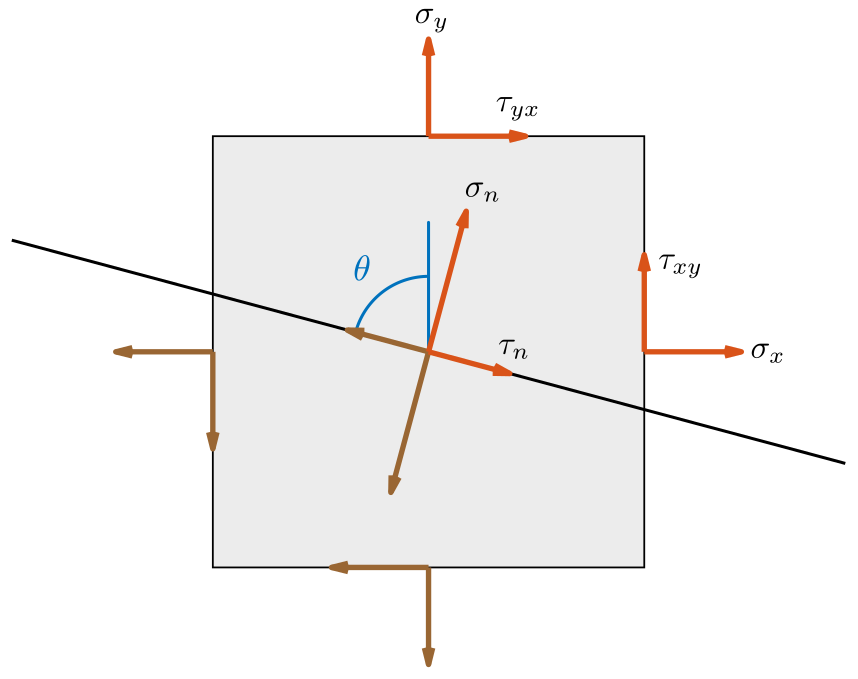

*Labeled diagram of the plane stresses. *

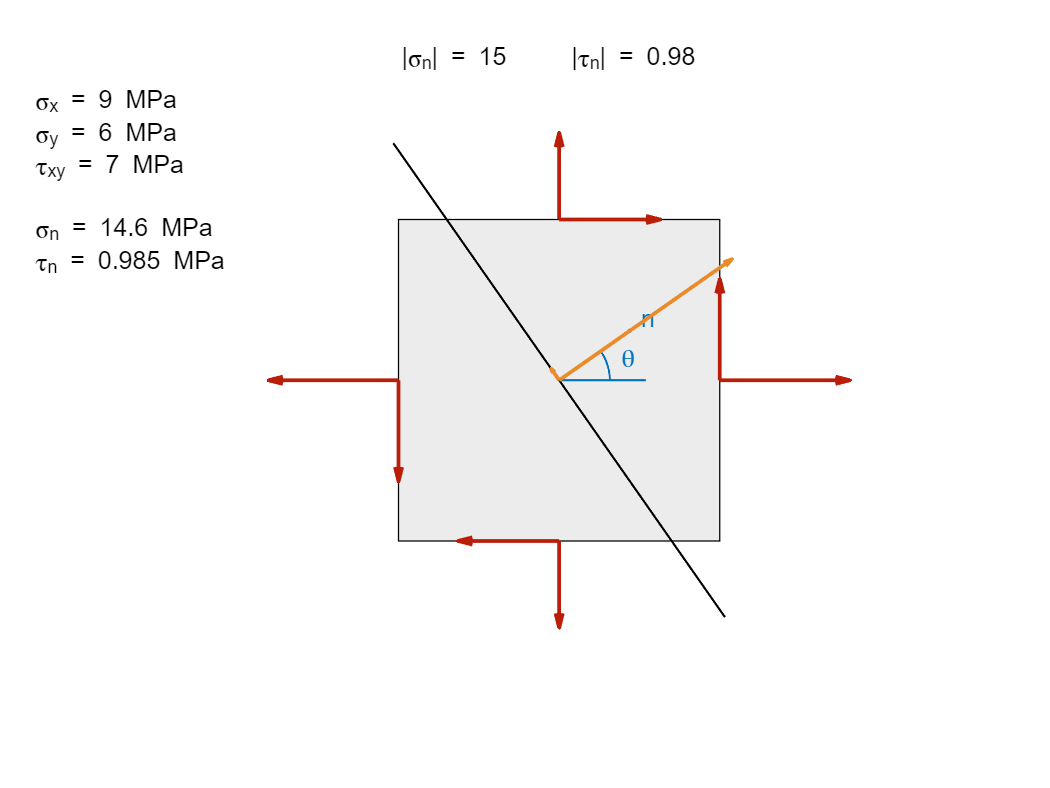

thetad =35; % Degrees
sigmax =9; % MPa
sigmay =6; % MPa
tauxy = 7; % MPa

show2DStressPlot(thetad,sigmax,sigmay,tauxy);

Matrix computation of the normal shear stress:

N = [cosd(thetad); sind(thetad)]

N =     0.8192
    0.5736


S = [sigmax, tauxy; tauxy, sigmay]

S =      9     7
     7     6


sigmaN = N'*S*N

sigmaN = 14.5909

function show2DStressPlot(thetad,sigmax,sigmay,tauxy)
    [sigman, taun] = plotStress2D(thetad,sigmax,sigmay,tauxy);    
    % Display stress values
    annotation("textbox",[0.02,0.6,0.3,0.3],"String",...
               "\sigma_x = " + num2str(sigmax,3) + " MPa" + newline + ...
               "\sigma_y = " + num2str(sigmay,3) + " MPa" + newline + ...
               "\tau_{xy} = " + num2str(tauxy,3) + " MPa" + newline + newline + ...
               "\sigma_n = " + num2str(sigman,3) + " MPa" + newline + ...
               "\tau_n = " + num2str(taun,3) + " MPa" + newline, ...
               "EdgeColor","None")
end